# Tutorial 8: Workspace Analysis (Part 1)

This tutorial will show how workspace analysis can be run in CASPR for cable-driven robots. This tutorial will use the ideas from the following previous tutorials:

- `T1_load_robot.mlx`

This tutorial shows how to perform workspace analysis through two approaches:

- WorkspaceSimulator

- Writing your own loops

## Setup (required for both approaches)

### Load the robot and trajectory

Load a robot as shown in `T1_load_robot.mlx`. A 2 DoF robot is first selected 

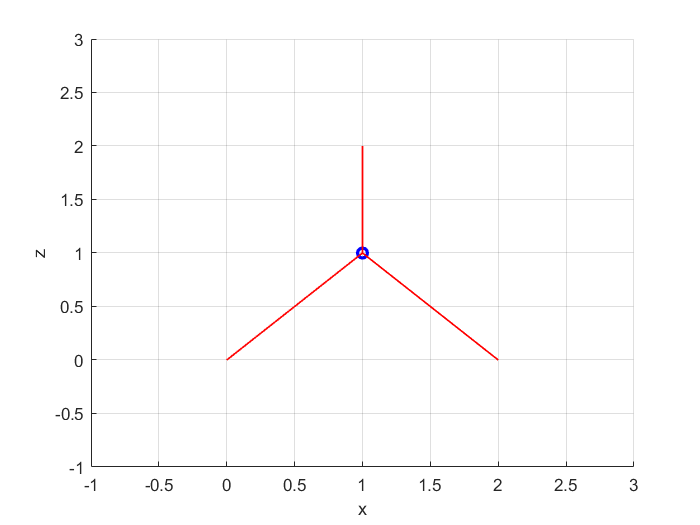

model_config = ModelConfig('Example point mass XZ');
cdpr_model = model_config.getModel('3_cables');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Setup the point-wise grid

A uniform (equal spacing) grid will be setup representing the set of points which the workspace analysis will be run.

% Set up the workspace simulator
% First the grid
q_min           = 0.1*ones(cdpr_model.numDofs, 1);
q_max           = 1.9*ones(cdpr_model.numDofs, 1);
q_step          = 0.1*ones(cdpr_model.numDofs, 1); 
uniform_grid    = UniformGrid(q_min, q_max, q_step,'step_size');

### Setup the workspace conditions and metrics

A range of conditions and metrics can be set to be analysed within the workspace analysis. 

For the types of metrics that can be studied, refer to the `~/src/Analysis/Workspace/JointSpaceWorkspace/Points/Metrics`.

For point-wise workspace, the following workspace conditions can be computed:

- Static Workspace: `WorkspaceStaticCondition`

- Wrench-Closure Workspace:` WrenchClosureCondition`

- Wrench-Feasible Workspace:` WrenchFeasibleCondition`

- Cable Interference-Free Workspace:` InterferenceFreeCondition`

In this example, the static workspace will be first computed:

ws_conditions   = {WorkspaceStaticCondition([])};

## 1) Solve using the PointWorkspaceSimulator

The `PointWorkspaceSimulator` allows the point-wise workspace to be run. 

First, create the simulator object using the robot model, grid and workspace condition(s):

workspace_sim = PointWorkspaceSimulator(cdpr_model, uniform_grid, ws_conditions, [], []);

Next, run the simulator over the specified grid:

workspace_sim.run();

[INFO] Workspace point 1. Completion Percentage: 0.28
[INFO] Workspace point 2. Completion Percentage: 0.55
[INFO] Problem infeasible
[INFO] Workspace point 3. Completion Percentage: 0.83
[INFO] Problem infeasible
[INFO] Workspace point 4. Completion Percentage: 1.11
[INFO] Problem infeasible
[INFO] Workspace point 5. Completion Percentage: 1.39
[INFO] Problem infeasible
[INFO] Workspace point 6. Completion Percentage: 1.66
[INFO] Problem infeasible
[INFO] Workspace point 7. Completion Percentage: 1.94
[INFO] Problem infeasible
[INFO] Workspace point 8. Completion Percentage: 2.22
[INFO] Problem infeasible
[INFO] Workspace point 9. Completion Percentage: 2.49
[INFO] Problem infeasible
[INFO] Workspace point 10. Completion Percentage: 2.77
[INFO] Problem infeasible
[INFO] Workspace point 11. Completion Percentage: 3.05
[INFO] Problem infeasible
[INFO] Workspace point 12. Completion Percentage: 3.32
[INFO] Problem infeasible
[INFO] Workspace point 13. Completion Percentage: 3.60
[INFO] P

Finally, plot the resulting 2-D workspace:

Set the desired axis as x-y axis in 2D

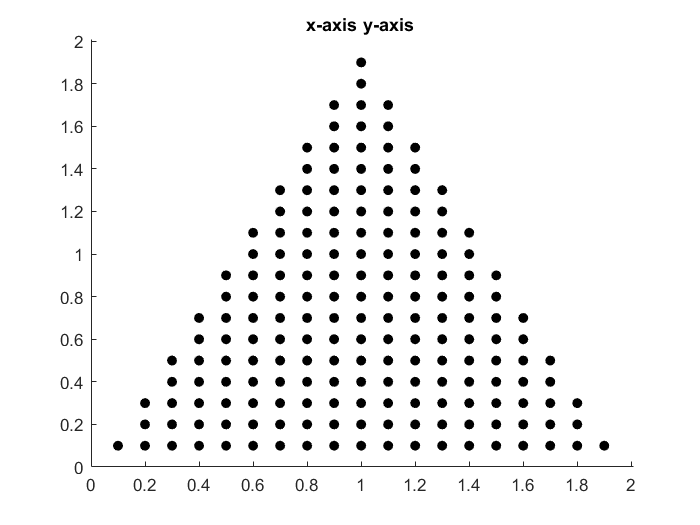

Plot updated


plot_axis = [1 2];

workspace_sim.workspace.plotWorkspace(plot_axis, ws_conditions, [], []);

## 2) Writing your own time loop (to be completed)

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop. The following simple example is basically what happens within the `ControllerSimulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

% q_soln = zeros(cdpr_model.numDofs, length(trajectory_ref.timeVector)); % Each column is the solution at each time step
% q_dot_soln = zeros(cdpr_model.numDofs, length(trajectory_ref.timeVector)); % Each column is the solution at each time step
% q_ddot_soln = zeros(cdpr_model.numDofs, length(trajectory_ref.timeVector)); % Each column is the solution at each time step
% force_soln = zeros(cdpr_model.numActuators, length(trajectory_ref.timeVector)); % Each column is the solution at each time step

Setup some initial variables for the joint space:

% q_soln(:, 1) = q_init;
% q_dot_soln(:, 1) = q_dot_init;
% q_ddot_soln(:, 1) = q_ddot_init;

Next, loop through the trajectory as a function of time:

% for t = 1:length(trajectory_ref.timeVector)-1

Execute the controller with the current joint states and reference trajectory (note that zero disturbance is applied) to determine the cable force command:

%     [force_soln(:, t), ~, ~, controller_exit_type] = controller.execute(q_soln(:, t), q_dot_soln(:, t), q_ddot_soln(:, t), trajectory_ref.q{t}, trajectory_ref.q_dot{t}, trajectory_ref.q_ddot{t}, zeros(cdpr_model.numDofs, 1), trajectory_ref.timeVector(t)); 

If controller exit type is not ControllerExitType.NO_ERROR, then it means that the controller didn't run to completion and hence should quit from the time loop.

%     if controller_exit_type ~= ControllerExitType.NO_ERROR
%         CASPR_log.Info('The controller simulation did not complete and hence nothing will be plotted');
%         break;
%     end

And if controller was successful, then execute the forward dynamics with the cable force solution from the controller to determine the next joint states (for the next iteration):

%     [q_soln(:,t+1), q_dot_soln(:,t+1), q_ddot_soln(:,t+1), cdpr_model] = ...
%         fd_solver.compute(q_soln(:, t), q_dot_soln(:, t), force_soln(:, t), cdpr_model.cableModel.cableIndicesActive, zeros(cdpr_model.numDofs, 1), trajectory_ref.timeStep, cdpr_model);
% end

The results can be plotted the way you desire yourself if there was no error. Starting with the reference and solution joint trajectory:

% if controller_exit_type == ControllerExitType.NO_ERROR
%     figure; 
%     plot(trajectory_ref.timeVector, q_soln, 'LineWidth', 1.5);
%     hold on;
%     plot(trajectory_ref.timeVector, cell2mat(trajectory_ref.q), '--', 'LineWidth', 1.5);
%     hold off;
%     title('Joint space');

Then the cable force solution from the controller:

%     figure; 
%     plot(trajectory_ref.timeVector, force_soln, '.', 'LineWidth', 1.5);
%     title('Cable forces');

Finally the tracking error:

%     figure; 
%     plot(trajectory_ref.timeVector, cell2mat(trajectory_ref.q) - q_soln, 'LineWidth', 1.5);
%     title('Joint space error');
% end